
$$m u'' + \gamma u' + ku = \cos(\omega t), \qquad u(0)=u'(0)=0$$


## Pure cosine forcing

Solving the harmonic oscillator with a unit cosine forcing, we can find the maximum amplitude of the result, or *gain*.

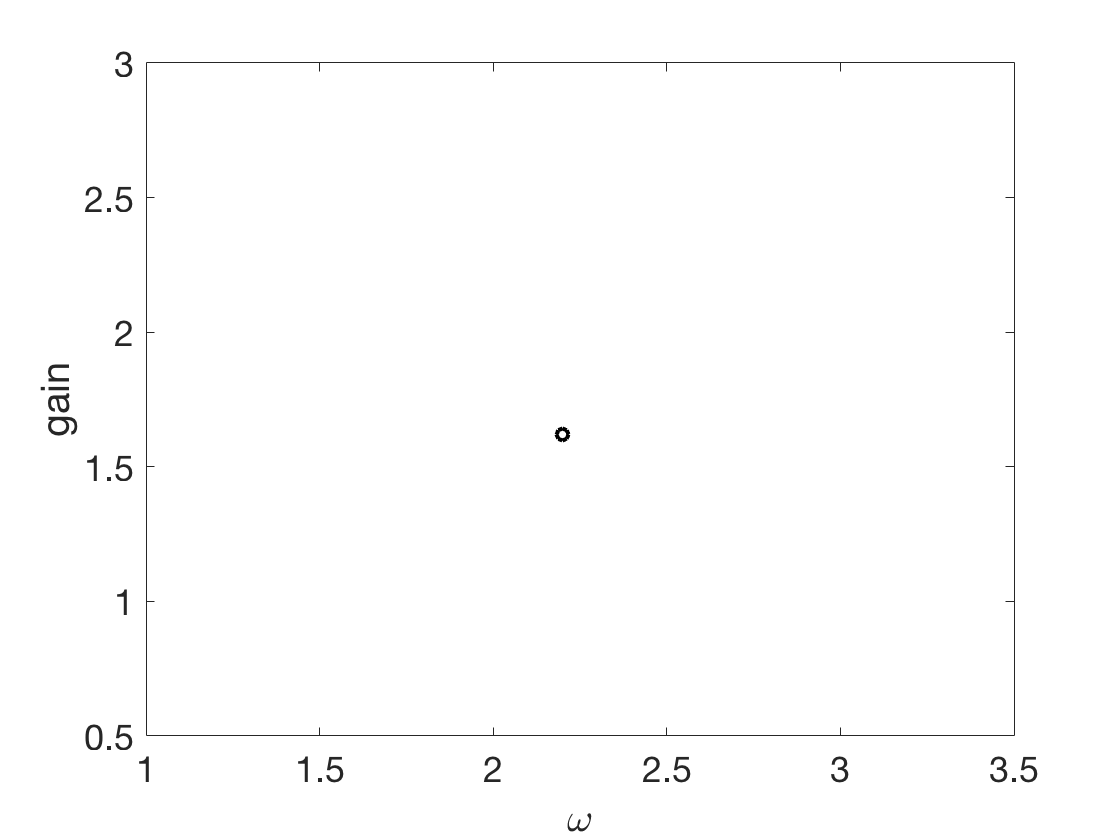

m = 1;  gamma = 0.02;  k = 6;
L = chebop([0 40]);
L.op = @(u) m*diff(u,2) + gamma*diff(u) + k*u;
L.lbc = [0 0]; 
t = chebfun('t',[0 40]);   clf
omega = 2.2;
u = L \ cos(omega*t);   G = max(abs(u));
clf, plot(omega,G,'ko')
xlabel('\omega'), ylabel('gain')

By looping over the forcing frequency, we see a spike in the gain. (This can all be worked out analytically.)

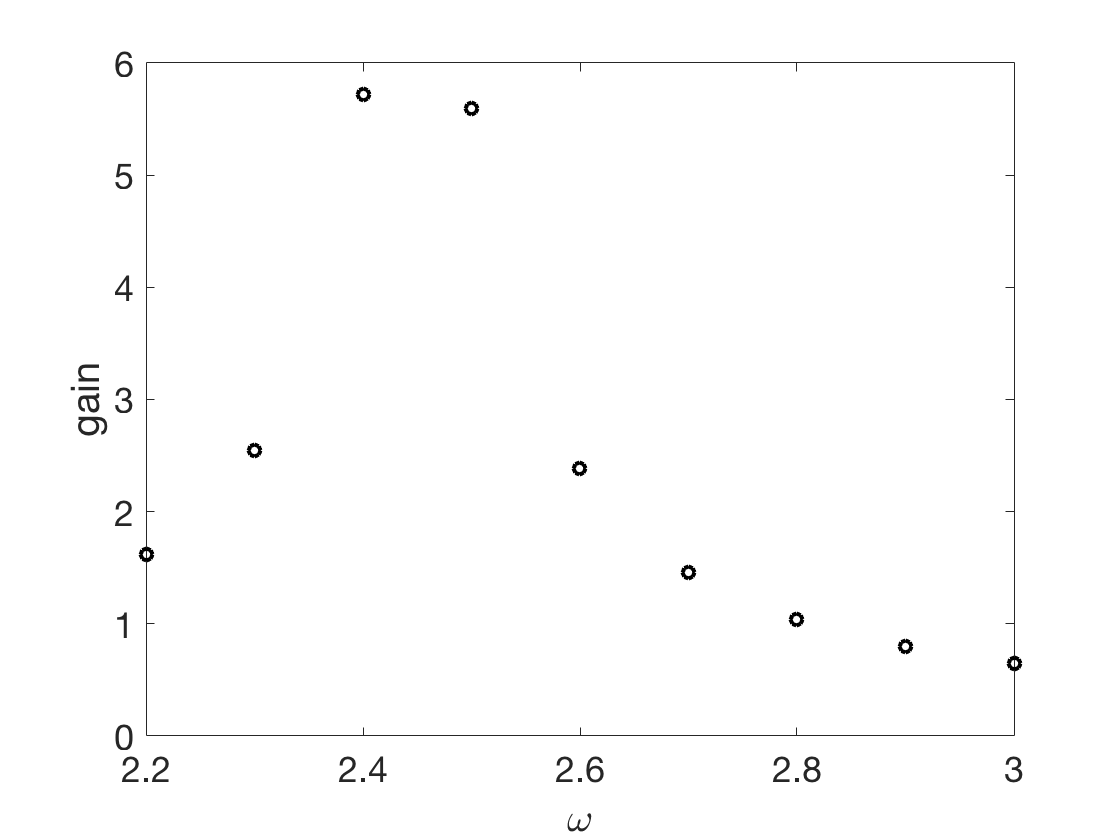

for omega = 2.3:.1:3
    u = L \ cos(omega*t);   G = max(abs(u));
    hold on, plot(omega,G,'ko')
end

## Chirped forcing

Another way of seeing the resonance is to use a "chirped" forcing, in which the frequency slowly increases. 

L.domain = [0 600];
t = chebfun('t',[0 600]);
omega = 2 + t/600

omega =
   chebfun column (1 smooth piece)
       interval       length     endpoint values  
[       0,   6e+02]        2         2        3 
vertical scale =   3 


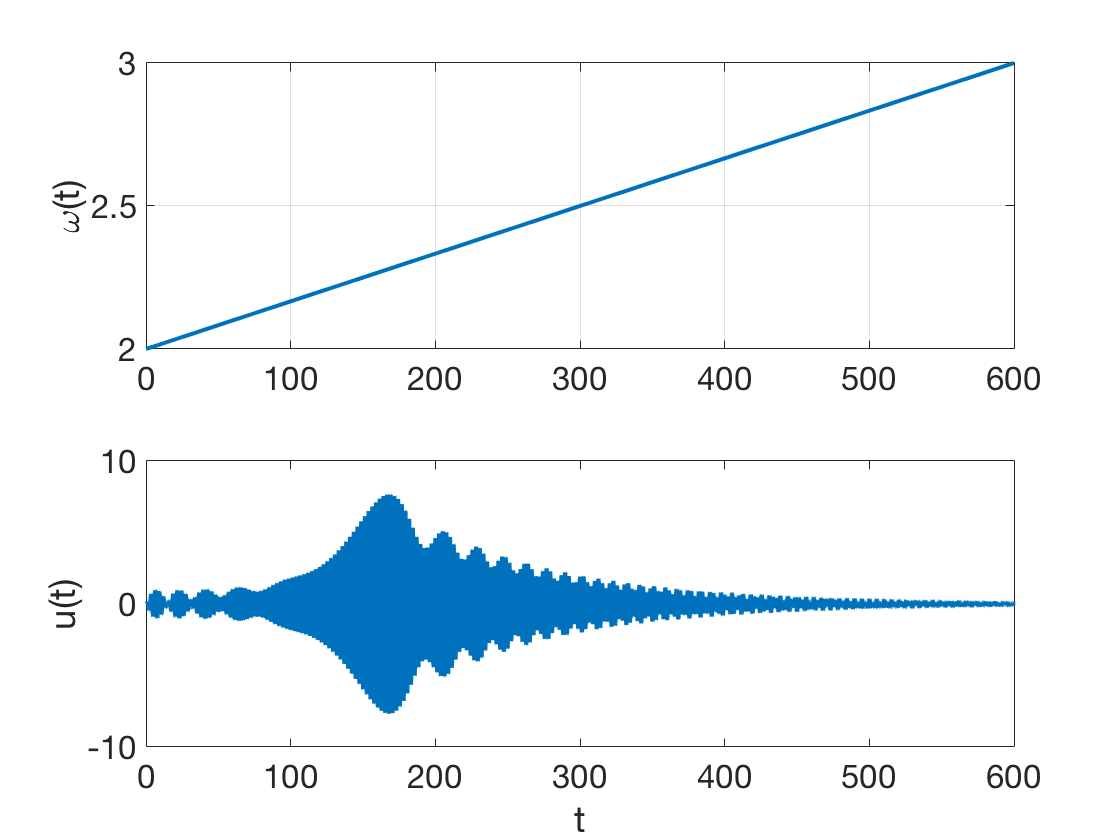


u = L \ cos(omega*t);

subplot(2,1,1), plot(omega)
ylabel('\omega(t)'), grid on
subplot(2,1,2), plot(u)
ylabel('u(t)'), xlabel('t')